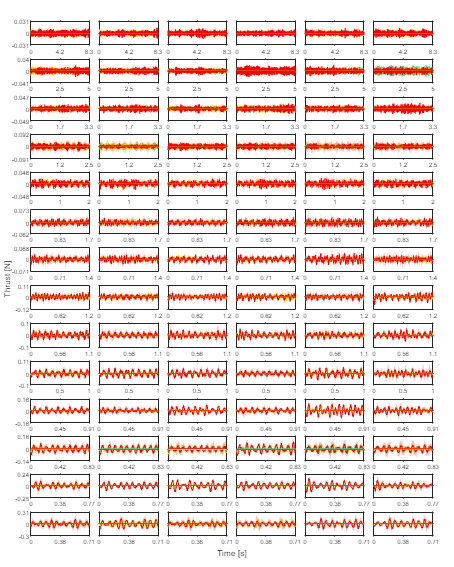

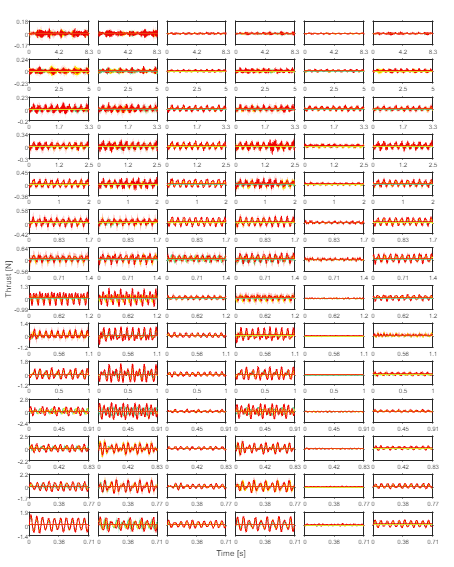

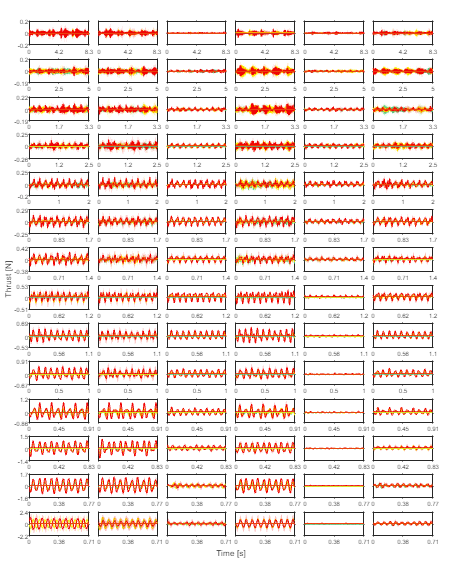

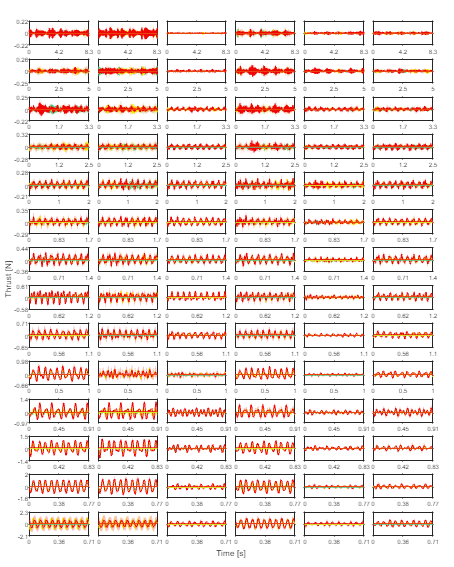

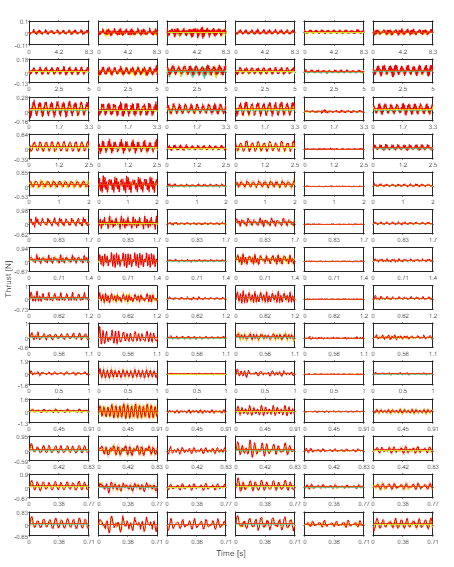

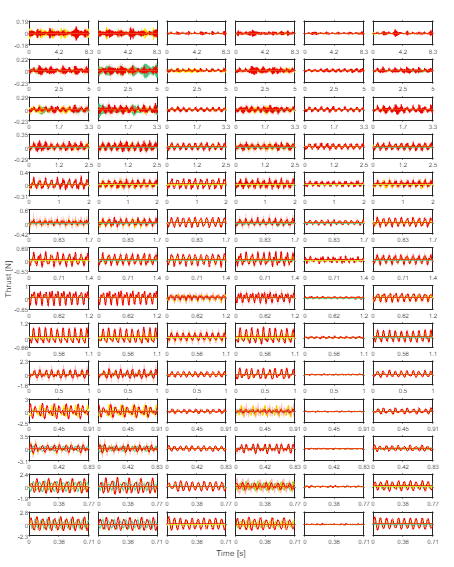

clear; clc;

root = 'data\fin-oscillation';

finType = {'eel'; 'trout'; 'mackeral'; 'tuna'; 'boxfish'; 'average'};
material = {'petg+petg'; 'petg+tpu'; 'tpu+tpu'};
thickness = {'-const'; '-conic'};
frequency = {'0.6Hz'; '1Hz'; '1.5Hz'; '2Hz'; '2.5Hz'; '3Hz'; '3.5Hz'; ...
             '4Hz'; '4.5Hz'; '5Hz'; '5.5Hz'; '6Hz'; '6.5Hz'; '7Hz'};
amplitude = {'A0.15'; 'A0.18'; 'A0.21'};

frequency_num = [0.6 1 1.5 2 2.5 3 3.5 4 4.5 5 5.5 6 6.5 7];
amplitude_num = [21.68 26.32 31.15
                 18.92 22.90 27.00
                 18.60 22.51 26.53
                 19.25 23.30 27.49
                 13.44 16.19 18.99
                 21.68 26.32 31.15];
amplitude_trail_num = [0.15 0.18 0.21];

colors = hex2rgb(['4DD091'; 'FEF001'; 'F00505']);

rows = length(frequency);                    % 14
cols = length(material) * length(thickness); % 6

tileW = 2.8;   % cm
tileH = 1.5;   % cm

FinID = 1;
DataTab = table();

for m = 1:length(finType)

    fig = figure;
    fig.Units = 'centimeters';
    fig.Position = [2 2 cols*tileW rows*tileH];

    tlo = tiledlayout(rows, cols, ...
        'TileSpacing', 'compact', ...
        'Padding', 'compact');

    % collect axes so we can format later if needed
    axMat = gobjects(rows, cols);
    yRowMin = inf(rows,1);
    yRowMax = -inf(rows,1);

    for k = 1:length(material)
        for l = 1:length(thickness)

            colIdx = (k-1)*length(thickness) + l;

            for i = 1:length(frequency)

                rowIdx = i;
                tileIdx = (rowIdx-1)*cols + colIdx;

                ax = nexttile(tileIdx);
                axMat(rowIdx, colIdx) = ax;
                hold(ax, 'on')

                for j = 1:length(amplitude)

                    meta = struct( ...
                        'FinID', FinID, ...
                        'FinType', m, ...
                        'Material', k, ...
                        'Thickness', l, ...
                        'Frequency', frequency_num(i), ...
                        'Amplitude', amplitude_trail_num(j), ...
                        'AngleAmplitude', str2double(amplitude{j}));

                    files = dir([root '\' finType{m} '\' material{k} thickness{l} '\' ...
                                 frequency{i} '\' amplitude{j} '\*.mat']);

                    [Tab, ymin, ymax] = beatanalysis(files, ax, colors(j,:), meta);
                    DataTab = [DataTab; Tab];

                    yRowMin(rowIdx) = min(yRowMin(rowIdx), ymin);
                    yRowMax(rowIdx) = max(yRowMax(rowIdx), ymax);
                end

                % ----- axis formatting -----
                ax.FontUnits = 'points';
                ax.FontSize = 5;
                ax.Box = 'on';
                ax.TickDir = 'out';

                % 5 beats shown
                fHz = frequency_num(i);
                xEnd = 5 / fHz;
                xlim(ax, [0 xEnd]);

                % x ticks adapted to each frequency
                xticks = [0, xEnd/2, xEnd];
                ax.XTick = xticks;
                ax.XTickLabel = arrayfun(@(v) sprintf('%.2g', v), xticks, 'UniformOutput', false);

                hold(ax, 'off')
            end

            FinID = FinID + 1;
        end
    end

for i = 1:rows

    yrange = yRowMax(i) - yRowMin(i);
    pad = 0.1 * yrange;

    yMin = yRowMin(i) - pad;
    yMax = yRowMax(i) + pad;

    yticks = [yMin, 0, yMax];

    for j = 1:cols
        ax = axMat(i,j);

        ylim(ax, [yMin yMax])

        ax.YTick = yticks;

        % Only show labels on first column
        if j == 1
            ax.YTickLabel = arrayfun(@(v) sprintf('%.2g', v), yticks, 'UniformOutput', false);
        else
            ax.YTickLabel = [];
        end
    end
end

    xlabel(tlo, 'Time [s]', 'FontSize', 7)
    ylabel(tlo, 'Thrust [N]', 'FontSize', 7)

    fig.PaperUnits = 'centimeters';
    fig.PaperSize = fig.Position(3:4);
    fig.PaperPosition = [0 0 fig.Position(3:4)];

    exportgraphics(fig, ['grid_' finType{m} '.pdf'], ...
    'ContentType','image', ...
    'Resolution',1200)
end


writetable(DataTab, 'fin_results.csv');

disp(DataTab);

clear; clc;

load('fin_results.mat')

DataTab.FinID = categorical(DataTab.FinID);
DataTab.FinType = categorical(DataTab.FinType);
DataTab.Material = categorical(DataTab.Material);
DataTab.Thickness = categorical(DataTab.Thickness);
DataTab.ExperimentID = categorical(DataTab.ExperimentID);
DataTab.Frequency = categorical(DataTab.Frequency);
DataTab.Amplitude = categorical(DataTab.Amplitude);

fullFormula = ['Thrust ~ FinType + Material + Thickness + Frequency + Amplitude' ...
       '+ FinType:Frequency + Material:Frequency + Thickness:Frequency + Amplitude:Frequency' ...
       '+ (1|FinID)'];

fullFormula = 'Thrust ~ FinType*Material*Thickness*Frequency*Amplitude + (1|FinID)';

lme_full = fitlme(DataTab, fullFormula);

disp(lme_full);
anova(lme_full)           % tests for fixed effects (approximate F-tests)

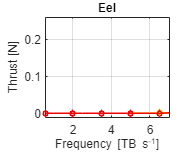

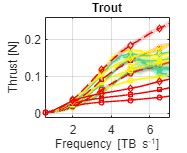

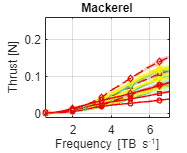

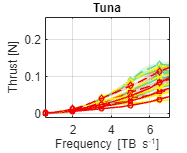

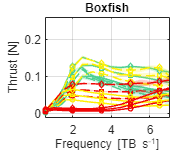

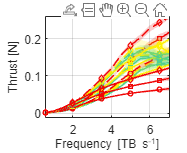

clear; clc;

load('fin_results.mat')

alpha = 0.05;

%% Definitions

finType = {'eel'; 'trout'; 'mackeral'; 'tuna'; 'boxfish'; 'average'};
fins = {'Eel'; 'Trout'; 'Mackerel'; 'Tuna'; 'Boxfish'; 'Average'};

material = {'petg+petg'; 'petg+tpu'; 'tpu+tpu'};
material_names = {'Rigid'; 'Semi-Soft'; 'Soft'};

thickness = {'-const'; '-conic'};
thickness_names = {'Constant thickness'; 'Conical thickness'};

frequency_num = [0.6 1 1.5 2 2.5 3 3.5 4 4.5 5 5.5 6 6.5 7];
amplitude_num = [0.15 0.18 0.21];
amplitude_names = {'0.15', '0.18', '0.21'};

colors = hex2rgb(['4DD091'; 'FEF001'; 'F00505']); % materials
lineStyle = {'-','--'};                           % thickness
markers = {'o','s','d'};                          % amplitudes

%% Figure sizes [cm]
plotW = 5.5;
plotH = 4.5;

legendW = 14.0;
legendH = 2.8;

%% Choose response variable
if ismember('ThrustMean', DataTab.Properties.VariableNames)
    yvar = 'ThrustMean';
else
    yvar = 'Thrust';
end

%% Compute grouped statistics including amplitude

[G, fin, mat, thk, freq, amp] = findgroups( ...
    DataTab.FinType, DataTab.Material, DataTab.Thickness, ...
    DataTab.Frequency, DataTab.Amplitude);

Mean = splitapply(@mean,  DataTab.(yvar), G);
Std  = splitapply(@std,   DataTab.(yvar), G);
n    = splitapply(@numel, DataTab.(yvar), G);

Cond = table(fin, mat, thk, freq, amp, Mean, Std, n, ...
    'VariableNames', ...
    {'FinType','Material','Thickness','Frequency','Amplitude','Mean','Std','n'});

%% Bonferroni correction

finLevels = unique(DataTab.FinType);
matLevels = unique(DataTab.Material);
thkLevels = unique(DataTab.Thickness);
ampLevels = unique(DataTab.Amplitude);

nComb = numel(matLevels) * numel(thkLevels) * numel(ampLevels);
nComparisons = nchoosek(nComb, 2);
alphaAdj = alpha / nComparisons;

Cond.CI = tinv(1 - alphaAdj/2, Cond.n - 1) .* Cond.Std ./ sqrt(Cond.n);

%% Make the six fin figures WITHOUT legends and save as PDF

for f = 1:numel(finLevels)

    fig = figure('Color','w');
    hold on

    Tf = Cond(Cond.FinType == finLevels(f), :);

    for a = 1:numel(amplitude_num)
        for m = 1:numel(material)
            for t = 1:numel(thickness)

                idx = Tf.Material == matLevels(m) & ...
                      Tf.Thickness == thkLevels(t) & ...
                      Tf.Amplitude == amplitude_num(a);

                Tsub = Tf(idx,:);

                if isempty(Tsub)
                    continue
                end

                [freqSorted, order] = sort(Tsub.Frequency);
                meanVals = Tsub.Mean(order);
                ciVals   = Tsub.CI(order);

                % CI shaded region
                patch([freqSorted; flipud(freqSorted)], ...
                      [meanVals-ciVals; flipud(meanVals+ciVals)], ...
                      colors(m,:), ...
                      'FaceAlpha', 0.2, ...
                      'EdgeColor', 'none', ...
                      'HandleVisibility', 'off');

                % Mean line
                plot(freqSorted, meanVals, ...
                    'Color', colors(m,:), ...
                    'LineStyle', lineStyle{t}, ...
                    'Marker', markers{a}, ...
                    'LineWidth', 1.2, ...
                    'MarkerSize', 4,'MarkerIndices', 1:3:14);
            end
        end
    end

    grid on
    box on
    xlabel('Frequency [TB s^{-1}]','Interpreter','tex')
    ylabel('Thrust [N]','Interpreter','tex')
    title(fins{f}, 'Interpreter', 'tex')
    xlim([0.6 7])
    ylim([-0.01 0.26])

    fontsize(10,'points');

    set(fig, 'Units', 'centimeters', ...
             'Position', [2 2 plotW plotH]);

    set(fig, 'PaperUnits', 'centimeters');
    set(fig, 'PaperSize', [plotW plotH]);
    set(fig, 'PaperPosition', [0 0 plotW plotH]);
    set(fig, 'PaperPositionMode', 'manual');

    drawnow;

    hold off

    %print(fig, ['fin_' lower(fins{f}) '.pdf'], '-dpdf', '-vector');
end


%% Find best configuration per fin across ALL amplitudes too

BestTable = table('Size',[0 6], ...
    'VariableTypes', {'string','string','string','double','double','double'}, ...
    'VariableNames', {'FinType','BestMaterial','BestThickness','BestAmplitude', ...
                      'OptimalFrequency','MaxThrust'});

for f = 1:numel(finLevels)

    Tf = Cond(Cond.FinType == finLevels(f), :);

    [mx, idx] = max(Tf.Mean);
    bestRow = Tf(idx,:);

    BestTable = [BestTable; ...
        {string(bestRow.FinType), ...
         string(bestRow.Material), ...
         string(bestRow.Thickness), ...
         bestRow.Amplitude, ...
         bestRow.Frequency, ...
         mx}];
end

disp('Best configuration per fin across all amplitudes:')

Best configuration per fin across all amplitudes:


disp(BestTable)

    FinType    BestMaterial    BestThickness    BestAmplitude    OptimalFrequency    MaxThrust
    _______    ____________    _____________    _____________    ________________    _________

      "1"          "2"              "1"             0.21                 7           0.0016131
      "2"          "3"              "2"             0.21                 7             0.24199
      "3"          "3"              "2"             0.21                 7             0.15227
      "4"          "1"              "2"             0.21               6.5             0.13239
      "5"          "2"              "2"             0.21               2.5             0.15185
      "6"          "3"              "2"             0.21                 7             0.25639



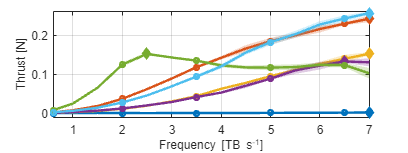


%% Plot best configuration of each fin in one figure
plotbcW = 12;
plotbcH = 4.5;

fig = figure('Color','w'); hold on

bestColors = lines(numel(finLevels));
legendHandles = gobjects(numel(finLevels),1);
legendNames = strings(numel(finLevels),1);

for f = 1:numel(finLevels)

    bestMat = BestTable.BestMaterial(f);
    bestThk = BestTable.BestThickness(f);
    bestAmp = BestTable.BestAmplitude(f);

    idx = string(Cond.FinType)   == BestTable.FinType(f) & ...
          string(Cond.Material)  == bestMat & ...
          string(Cond.Thickness) == bestThk & ...
          Cond.Amplitude         == bestAmp;

    Tbest = Cond(idx,:);

    [freqSorted, order] = sort(Tbest.Frequency);
    meanVals = Tbest.Mean(order);
    ciVals   = Tbest.CI(order);

    patch([freqSorted; flipud(freqSorted)], ...
          [meanVals-ciVals; flipud(meanVals+ciVals)], ...
          bestColors(f,:), ...
          'FaceAlpha', 0.25, ...
          'EdgeColor', 'none', ...
          'HandleVisibility', 'off');

    h = plot(freqSorted, meanVals, ...
        'LineWidth', 2, ...
        'Color', bestColors(f,:));

    plot(BestTable.OptimalFrequency(f), BestTable.MaxThrust(f), 'd', ...
        'MarkerSize', 7, ...
        'MarkerFaceColor', bestColors(f,:), ...
        'MarkerEdgeColor', bestColors(f,:));
end

grid on; box on
xlabel('Frequency [TB s^{-1}]','Interpreter','tex')
ylabel('Thrust [N]','Interpreter','tex')
xlim([0.6 7])
ylim([-0.01 0.26])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotbcW plotbcH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotbcW plotbcH]);
set(fig, 'PaperPosition', [0 0 plotbcW plotbcH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'fin_best_config.pdf', '-dpdf', '-vector');


%% Pairwise Bonferroni tests at optimal frequency and best amplitude for each fin

for f = 1:numel(finLevels)

    fprintf('\n==== %s ====\n', fins{f})

    optFreq = BestTable.OptimalFrequency(f);
    bestAmp = BestTable.BestAmplitude(f);

    Topt = DataTab( ...
        DataTab.FinType == finLevels(f) & ...
        DataTab.Frequency == optFreq & ...
        DataTab.Amplitude == bestAmp, :);

    combos = unique(Topt(:,{'Material','Thickness'}));

    for i = 1:height(combos)
        for j = i+1:height(combos)

            idx1 = Topt.Material == combos.Material(i) & ...
                   Topt.Thickness == combos.Thickness(i);

            idx2 = Topt.Material == combos.Material(j) & ...
                   Topt.Thickness == combos.Thickness(j);

            [~,p] = ttest2(Topt.(yvar)(idx1), ...
                           Topt.(yvar)(idx2), ...
                           'Alpha', alphaAdj);

            fprintf('M%s T%s vs M%s T%s   p = %.4f\n', ...
                string(combos.Material(i)), string(combos.Thickness(i)), ...
                string(combos.Material(j)), string(combos.Thickness(j)), ...
                p);
        end
    end
end


==== Eel ====


M1 T1 vs M1 T2   p = 0.0076
M1 T1 vs M2 T1   p = 0.4308
M1 T1 vs M2 T2   p = 0.2801
M1 T1 vs M3 T1   p = 0.8847
M1 T1 vs M3 T2   p = 0.3165
M1 T2 vs M2 T1   p = 0.0059
M1 T2 vs M2 T2   p = 0.1737
M1 T2 vs M3 T1   p = 0.0081
M1 T2 vs M3 T2   p = 0.1859
M2 T1 vs M2 T2   p = 0.1142
M2 T1 vs M3 T1   p = 0.5173
M2 T1 vs M3 T2   p = 0.1316
M2 T2 vs M3 T1   p = 0.2452
M2 T2 vs M3 T2   p = 0.9735
M3 T1 vs M3 T2   p = 0.2778



==== Trout ====


M1 T1 vs M1 T2   p = 0.0000
M1 T1 vs M2 T1   p = 0.0000
M1 T1 vs M2 T2   p = 0.0997
M1 T1 vs M3 T1   p = 0.0000
M1 T1 vs M3 T2   p = 0.0000
M1 T2 vs M2 T1   p = 0.0000
M1 T2 vs M2 T2   p = 0.0000
M1 T2 vs M3 T1   p = 0.0000
M1 T2 vs M3 T2   p = 0.0000
M2 T1 vs M2 T2   p = 0.0000
M2 T1 vs M3 T1   p = 0.0000
M2 T1 vs M3 T2   p = 0.0000
M2 T2 vs M3 T1   p = 0.0000
M2 T2 vs M3 T2   p = 0.0000
M3 T1 vs M3 T2   p = 0.0000



==== Mackerel ====


M1 T1 vs M1 T2   p = 0.5840
M1 T1 vs M2 T1   p = 0.0000
M1 T1 vs M2 T2   p = 0.0005
M1 T1 vs M3 T1   p = 0.0000
M1 T1 vs M3 T2   p = 0.0000
M1 T2 vs M2 T1   p = 0.0000
M1 T2 vs M2 T2   p = 0.0005
M1 T2 vs M3 T1   p = 0.0000
M1 T2 vs M3 T2   p = 0.0000
M2 T1 vs M2 T2   p = 0.0091
M2 T1 vs M3 T1   p = 0.0000
M2 T1 vs M3 T2   p = 0.0000
M2 T2 vs M3 T1   p = 0.0000
M2 T2 vs M3 T2   p = 0.0000
M3 T1 vs M3 T2   p = 0.0000



==== Tuna ====


M1 T1 vs M1 T2   p = 0.0000
M1 T1 vs M2 T1   p = 0.0000
M1 T1 vs M2 T2   p = 0.0055
M1 T1 vs M3 T1   p = 0.0000
M1 T1 vs M3 T2   p = 0.0048
M1 T2 vs M2 T1   p = 0.0000
M1 T2 vs M2 T2   p = 0.0000
M1 T2 vs M3 T1   p = 0.0000
M1 T2 vs M3 T2   p = 0.0000
M2 T1 vs M2 T2   p = 0.0000
M2 T1 vs M3 T1   p = 0.0000
M2 T1 vs M3 T2   p = 0.0000
M2 T2 vs M3 T1   p = 0.0000
M2 T2 vs M3 T2   p = 0.0000
M3 T1 vs M3 T2   p = 0.0000



==== Boxfish ====


M1 T1 vs M1 T2   p = 0.0000
M1 T1 vs M2 T1   p = 0.0000
M1 T1 vs M2 T2   p = 0.5745
M1 T1 vs M3 T1   p = 0.0000
M1 T1 vs M3 T2   p = 0.0000
M1 T2 vs M2 T1   p = 0.0000
M1 T2 vs M2 T2   p = 0.0000
M1 T2 vs M3 T1   p = 0.0000
M1 T2 vs M3 T2   p = 0.0000
M2 T1 vs M2 T2   p = 0.0000
M2 T1 vs M3 T1   p = 0.0000
M2 T1 vs M3 T2   p = 0.0000
M2 T2 vs M3 T1   p = 0.0000
M2 T2 vs M3 T2   p = 0.0000
M3 T1 vs M3 T2   p = 0.0000



==== Average ====


M1 T1 vs M1 T2   p = 0.0000
M1 T1 vs M2 T1   p = 0.0000
M1 T1 vs M2 T2   p = 0.0085
M1 T1 vs M3 T1   p = 0.0000
M1 T1 vs M3 T2   p = 0.0000
M1 T2 vs M2 T1   p = 0.0000
M1 T2 vs M2 T2   p = 0.0000
M1 T2 vs M3 T1   p = 0.0000
M1 T2 vs M3 T2   p = 0.0000
M2 T1 vs M2 T2   p = 0.0000
M2 T1 vs M3 T1   p = 0.0000
M2 T1 vs M3 T2   p = 0.0000
M2 T2 vs M3 T1   p = 0.0000
M2 T2 vs M3 T2   p = 0.0000
M3 T1 vs M3 T2   p = 0.0000


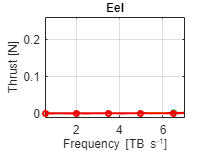

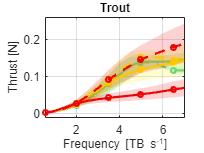

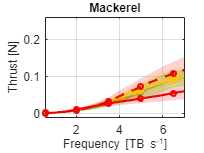

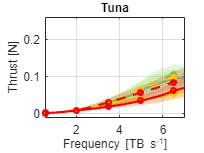

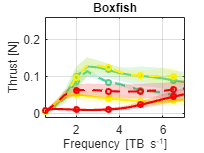

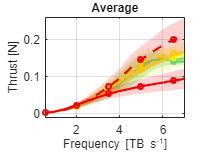

clear; clc;

load('fin_results.mat')

alpha = 0.05;

%% Definitions

finType = {'eel'; 'trout'; 'mackeral'; 'tuna'; 'boxfish'; 'average'};
fins = {'Eel'; 'Trout'; 'Mackerel'; 'Tuna'; 'Boxfish'; 'Average'};

material = {'petg+petg'; 'petg+tpu'; 'tpu+tpu'};
material_names = {'Rigid'; 'Semi-Soft'; 'Soft'};

thickness = {'-const'; '-conic'};
thickness_names = {'Constant thickness'; 'Conical thickness'};

frequency_num = [0.6 1 1.5 2 2.5 3 3.5 4 4.5 5 5.5 6 6.5 7];
amplitude_num = [0.15 0.18 0.21];
amplitude_names = {'0.15', '0.18', '0.21'};

colors = hex2rgb(['4DD091'; 'FEF001'; 'F00505']); % materials
lineStyle = {'-','--'};                           % thickness

%% Figure sizes [cm]
plotW = 6;
plotH = 4.5;

%% Choose response variable
if ismember('ThrustMean', DataTab.Properties.VariableNames)
    yvar = 'ThrustMean';
else
    yvar = 'Thrust';
end

%% Make sure variables are numeric if needed
DataTab.Frequency = double(DataTab.Frequency);
DataTab.Amplitude = double(DataTab.Amplitude);
DataTab.(yvar)    = double(DataTab.(yvar));

%% -------------------------------------------------------------
% 1) First compute mean response for each amplitude separately
%    (averaging over repetitions within each condition)
%% -------------------------------------------------------------
[G1, fin, mat, thk, freq, amp] = findgroups( ...
    DataTab.FinType, DataTab.Material, DataTab.Thickness, ...
    DataTab.Frequency, DataTab.Amplitude);

MeanAmp = splitapply(@mean,  DataTab.(yvar), G1);
StdAmp  = splitapply(@std,   DataTab.(yvar), G1);
nAmp    = splitapply(@numel, DataTab.(yvar), G1);

CondAmp = table(fin, mat, thk, freq, amp, MeanAmp, StdAmp, nAmp, ...
    'VariableNames', ...
    {'FinType','Material','Thickness','Frequency','Amplitude','MeanAmp','StdAmp','nAmp'});

%% -------------------------------------------------------------
% 2) Then collapse over amplitude for plotting:
%    central line = mean across amplitude means
%    shaded region = min/max across amplitude means
%% -------------------------------------------------------------
[G2, fin2, mat2, thk2, freq2] = findgroups( ...
    CondAmp.FinType, CondAmp.Material, CondAmp.Thickness, CondAmp.Frequency);

MeanAcrossAmp = splitapply(@mean, CondAmp.MeanAmp, G2);
MinAcrossAmp  = splitapply(@min,  CondAmp.MeanAmp, G2);
MaxAcrossAmp  = splitapply(@max,  CondAmp.MeanAmp, G2);

% Optional: adjusted CI for the central mean across amplitudes
% This is NOT the amplitude band, only uncertainty on the central line.
nAmpLevels = numel(amplitude_num);
nComparisons = nchoosek(nAmpLevels, 2);
alphaAdj = alpha / nComparisons;

StdAcrossAmp = splitapply(@std, CondAmp.MeanAmp, G2);
CIAcrossAmp  = tinv(1 - alphaAdj/2, nAmpLevels - 1) .* StdAcrossAmp ./ sqrt(nAmpLevels);

CondPlot = table(fin2, mat2, thk2, freq2, ...
    MeanAcrossAmp, MinAcrossAmp, MaxAcrossAmp, CIAcrossAmp, ...
    'VariableNames', ...
    {'FinType','Material','Thickness','Frequency', ...
     'MeanAcrossAmp','MinAcrossAmp','MaxAcrossAmp','CIAcrossAmp'});

%% Unique levels from the table
finLevels = unique(CondPlot.FinType);
matLevels = unique(CondPlot.Material);
thkLevels = unique(CondPlot.Thickness);

%% -------------------------------------------------------------
% 3) Make the fin figures
%% -------------------------------------------------------------
for f = 1:numel(finLevels)

    fig = figure('Color','w');
    hold on

    Tf = CondPlot(CondPlot.FinType == finLevels(f), :);

    for m = 1:numel(matLevels)
        for t = 1:numel(thkLevels)

            idx = Tf.Material == matLevels(m) & ...
                  Tf.Thickness == thkLevels(t);

            Tsub = Tf(idx,:);

            if isempty(Tsub)
                continue
            end

            [freqSorted, order] = sort(Tsub.Frequency);
            meanVals = Tsub.MeanAcrossAmp(order);
            lowVals  = Tsub.MinAcrossAmp(order);
            highVals = Tsub.MaxAcrossAmp(order);
            ciVals   = Tsub.CIAcrossAmp(order);

            % Shaded band showing amplitude spread (min to max over amplitudes)
            patch([freqSorted; flipud(freqSorted)], ...
                  [lowVals; flipud(highVals)], ...
                  colors(m,:), ...
                  'FaceAlpha', 0.18, ...
                  'EdgeColor', 'none', ...
                  'HandleVisibility', 'off');

            % Central mean line across amplitudes
            plot(freqSorted, meanVals, ...
                'Color', colors(m,:), ...
                'LineStyle', lineStyle{t}, ...
                'LineWidth', 1.8, ...
                'Marker', 'o', ...
                'MarkerSize', 4, ...
                'MarkerIndices', 1:3:numel(freqSorted));

            % Optional: Bonferroni-adjusted CI as faint dashed bounds
            % Uncomment if you want inferential uncertainty around the mean line
            % plot(freqSorted, meanVals + ciVals, ...
            %     'Color', colors(m,:), ...
            %     'LineStyle', ':', ...
            %     'LineWidth', 0.8, ...
            %     'HandleVisibility', 'off');
            %
            % plot(freqSorted, meanVals - ciVals, ...
            %     'Color', colors(m,:), ...
            %     'LineStyle', ':', ...
            %     'LineWidth', 0.8, ...
            %     'HandleVisibility', 'off');
        end
    end

    grid on
    box on
    xlabel('Frequency [TB s^{-1}]','Interpreter','tex')
    ylabel('Thrust [N]','Interpreter','tex')

    % If your fin labels are 1..5, this maps them safely
    thisFin = double(finLevels(f));
    if thisFin >= 1 && thisFin <= numel(fins)
        title(fins{thisFin}, 'Interpreter', 'tex')
    else
        title(sprintf('Fin %d', thisFin), 'Interpreter', 'tex')
    end

    xlim([0.6 7])
    ylim([-0.01 0.26])

    fontsize(10,'points');

    set(fig, 'Units', 'centimeters', ...
             'Position', [2 2 plotW plotH]);

    set(fig, 'PaperUnits', 'centimeters');
    set(fig, 'PaperSize', [plotW plotH]);
    set(fig, 'PaperPosition', [0 0 plotW plotH]);
    set(fig, 'PaperPositionMode', 'manual');

    drawnow;
    hold off

    % Safe filename
    if thisFin >= 1 && thisFin <= numel(fins)
        outName = ['fin_' lower(fins{thisFin}) '_ampAvg'];
    else
        outName = sprintf('fin_%d_ampAvg', thisFin);
    end

    print(fig, [outName '.pdf'], '-dpdf', '-vector');
end

%% =========================
%  BEST FIN OVERALL + ERROR BARS ON MAXIMA
%  Using BestTable from the "all amplitudes" version
%  =========================

alpha = 0.05;

% Use same response variable as earlier
if ismember('ThrustMean', DataTab.Properties.VariableNames)
    yvar = 'ThrustMean';
else
    yvar = 'Thrust';
end

nFin = height(BestTable);

% Bonferroni across all fin-to-fin comparisons
nFinComparisons = nchoosek(nFin,2);
alphaAdjFin = alpha / nFinComparisons;

% Collect per-fin "max condition" replicate stats
MaxTab = table('Size',[nFin 7], ...
    'VariableTypes', {'string','double','double','double','double','double','double'}, ...
    'VariableNames', {'FinType','MaxMean','CI_low','CI_high','n','MaxStd','OptimalFrequency'});

for i = 1:nFin

    % get this fin's optimal config from BestTable
    row = BestTable(i,:);

    fin = row.FinType;
    mat = row.BestMaterial;
    thk = row.BestThickness;
    amp = row.BestAmplitude;
    frq = row.OptimalFrequency;

    % raw replicates at optimal config
    idx = string(DataTab.FinType)   == fin & ...
          string(DataTab.Material)  == mat & ...
          string(DataTab.Thickness) == thk & ...
          DataTab.Amplitude         == amp & ...
          DataTab.Frequency         == frq;

    y = DataTab.(yvar)(idx);

    mu = mean(y,'omitnan');
    sd = std(y,'omitnan');
    nn = sum(~isnan(y));

    % Bonferroni-adjusted CI for the mean at the optimum condition
    tcrit = tinv(1 - alphaAdjFin/2, nn-1);
    halfw = tcrit * sd / sqrt(nn);

    MaxTab.FinType(i)          = fin;
    MaxTab.MaxMean(i)          = mu;
    MaxTab.MaxStd(i)           = sd;
    MaxTab.n(i)                = nn;
    MaxTab.CI_low(i)           = mu - halfw;
    MaxTab.CI_high(i)          = mu + halfw;
    MaxTab.OptimalFrequency(i) = frq;
end

% Determine best fin overall
[~,idxBest] = max(MaxTab.MaxMean);
BestOverallFin = MaxTab(idxBest,:);

disp("=== Max performance per fin (at each fin's best config) ===");

=== Max performance per fin (at each fin's best config) ===


disp(MaxTab)

    FinType     MaxMean       CI_low        CI_high     n      MaxStd      OptimalFrequency
    _______    _________    ___________    _________    _    __________    ________________

      "1"      0.0016131    -0.00037475    0.0036009    6    0.00092792            7       
      "2"        0.24199        0.23678      0.24721    6     0.0024332            7       
      "3"        0.15227        0.14983       0.1547    6     0.0011377            7       
      "4"        0.13239        0.13013      0.13466    6     0.0010585          6.5       
      "5"        0.15185        0.14924      0.15446    6     0.0012175          2.5       
      "6"        0.25639        0.25401      0.25878    6     0.0011137            7       




disp("=== Best fin overall ===");

=== Best fin overall ===


disp(BestOverallFin)

    FinType    MaxMean    CI_low     CI_high    n     MaxStd      OptimalFrequency
    _______    _______    _______    _______    _    _________    ________________

      "6"      0.25639    0.25401    0.25878    6    0.0011137           7        



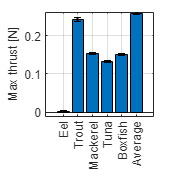


%% -------------------------
% Bar plot with error bars
% -------------------------
barplotW = 5;
barplotH = 5;

fig = figure('Color','w'); hold on
x = 1:nFin;

bar(x, MaxTab.MaxMean);

% error bars are half-width of CI
errLow  = MaxTab.MaxMean - MaxTab.CI_low;
errHigh = MaxTab.CI_high - MaxTab.MaxMean;

errorbar(x, MaxTab.MaxMean, errLow, errHigh, 'k.', 'LineWidth', 1);

grid on; box on
ylabel('Max thrust [N]','Interpreter','tex')
ylim([-0.01 0.26])

xticks(x)
xticklabels({'Eel' 'Trout' 'Mackerel' 'Tuna' 'Boxfish' 'Average'})
xtickangle(90)
fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 barplotW barplotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [barplotW barplotH]);
set(fig, 'PaperPosition', [0 0 barplotW barplotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'fin_bars.pdf', '-dpdf', '-vector');


%% -------------------------
% Pairwise fin comparisons (Bonferroni-adjusted p-values)
% Comparing raw thrust replicates at each fin's own optimum condition
% -------------------------
fprintf('\n=== Pairwise fin comparisons at each fin optimum (Bonferroni alpha = %.5g) ===\n', alphaAdjFin);


=== Pairwise fin comparisons at each fin optimum (Bonferroni alpha = 0.0033333) ===


1 vs 2: p = 7.04e-20
1 vs 3: p = 2.442e-20
1 vs 4: p = 6.598e-20
1 vs 5: p = 3.813e-20
1 vs 6: p = 1.125e-22
2 vs 3: p = 1.817e-15
2 vs 4: p = 2.18e-16
2 vs 5: p = 1.973e-15
2 vs 6: p = 1.203e-07
3 vs 4: p = 2.583e-11
3 vs 5: p = 0.5563
3 vs 6: p = 2.205e-18
4 vs 5: p = 4.61e-11
4 vs 6: p = 2.697e-19
5 vs 6: p = 3.03e-18


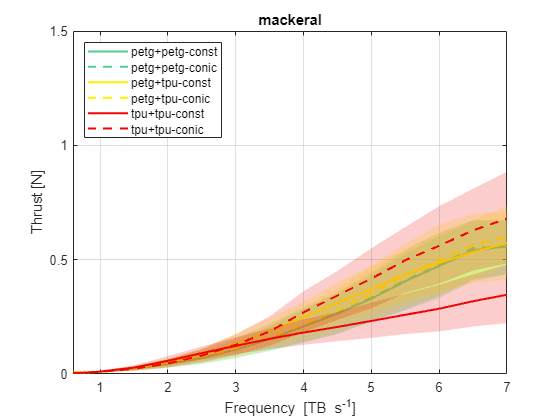

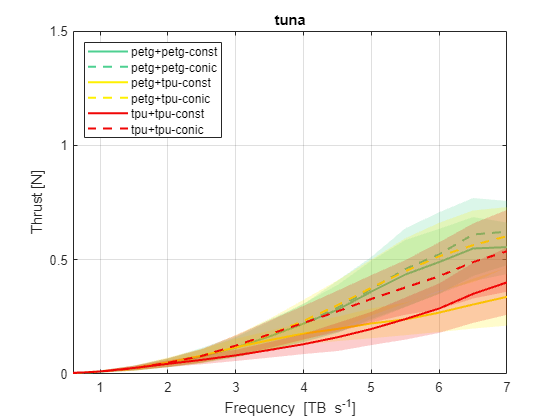

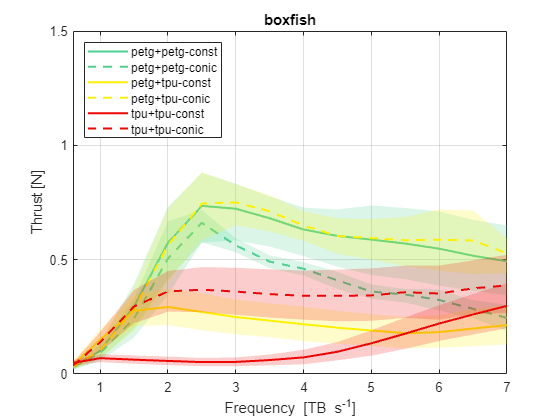

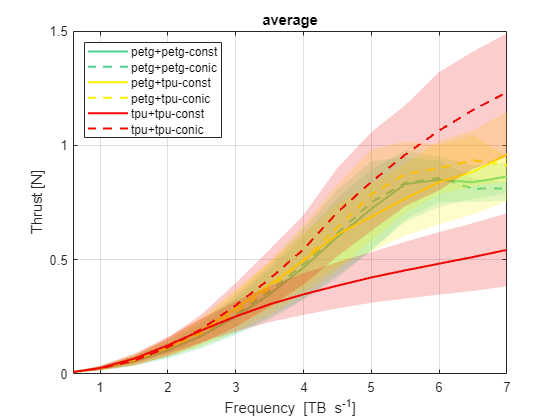

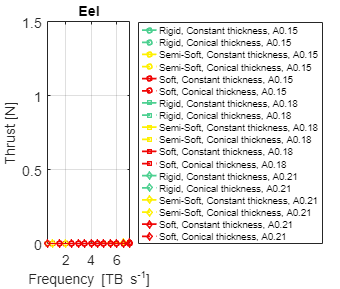

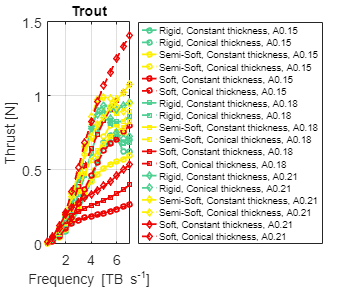

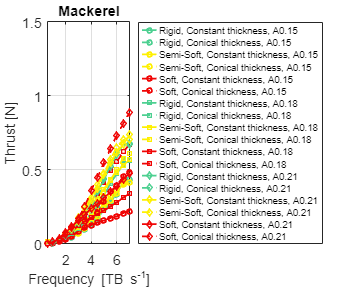

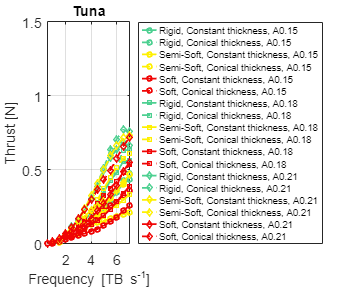

Error using  == 
Comparison is not defined between categorical and double arrays.

Linear mixed-effects model fit by ML

Model information:
    Number of observations            9072
    Fixed effects coefficients         154
    Random effects coefficients         36
    Covariance parameters                2

Formula:
    Thrust ~ 1 + FinType*Frequency + Material*Frequency + Thickness*Frequency + Frequency*Amplitude + (1 | FinID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -20899    -19789    10605            -21211  

Fixed effects coefficients (95% CIs):
    Name                                    Estimate       SE           tStat        DF      pValue         Lower          Upper      
    {'(Intercept)'                 }         -0.0048399     0.035608     -0.13592    8918        0.89189       -0.07464        0.06496
    {'FinType_2'                   }           0.010197     0.040839      0.24969    8918        0.80283      -0.069856        0.0

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                           FStat         DF1    DF2     pValue     
    {'(Intercept)'        }          0.018475     1     8918        0.89189
    {'FinType'            }             0.201     5     8918        0.96215
    {'Material'           }         0.0049019     2     8918        0.99511
    {'Thickness'          }        0.00051045     1     8918        0.98198
    {'Frequency'          }            31.046    13     8918     2.5757e-76
    {'Amplitude'          }           0.51547     2     8918        0.59724
    {'FinType:Frequency'  }            385.13    65     8918              0
    {'Material:Frequency' }            18.286    26     8918     1.0175e-81
    {'Thickness:Frequency'}             73.62    13     8918    4.2889e-186
    {'Frequency:Amplitude'}            59.724    26     8918    2.1255e-286


Added: FinType:Frequency                         AIC=-18449.51
Added: FinType:Material:Thickness:Frequency:Amplitude  AIC=-21450.35
Added: FinType:Frequency:Amplitude               AIC=-23786.42
Added: Material:Frequency                        AIC=-25213.86
Added: Thickness:Frequency                       AIC=-25553.39
Added: Thickness:Frequency:Amplitude             AIC=-25779.11
Added: Material:Frequency:Amplitude              AIC=-25929.26
Added: Material:Thickness:Frequency:Amplitude    AIC=-26066.51
Added: Frequency:Amplitude                       AIC=-26152.20
Added: Material:Thickness                        AIC=-26154.93



================ MODEL SELECTION SUMMARY ================


Final AIC: -26154.93



Selected additional effects:


  + FinType:Frequency
  + FinType:Material:Thickness:Frequency:Amplitude
  + FinType:Frequency:Amplitude
  + Material:Frequency
  + Thickness:Frequency
  + Thickness:Frequency:Amplitude
  + Material:Frequency:Amplitude
  + Material:Thickness:Frequency:Amplitude
  + Frequency:Amplitude
  + Material:Thickness



Effects NOT selected:


  - FinType:Amplitude
  - Material:Amplitude
  - Thickness:Amplitude



Final model formula:


  Thrust ~ FinType + Material + Thickness + Frequency + Amplitude + FinType:Frequency + FinType:Material:Thickness:Frequency:Amplitude + FinType:Frequency:Amplitude + Material:Frequency + Thickness:Frequency + Thickness:Frequency:Amplitude + Material:Frequency:Amplitude + Material:Thickness:Frequency:Amplitude + Frequency:Amplitude + Material:Thickness + (1|FinID)


Linear mixed-effects model fit by ML

Model information:
    Number of observations            9072
    Fixed effects coefficients         676
    Random effects coefficients         36
    Covariance parameters                2

Formula:
    Thrust ~ 1 + Material*Thickness + FinType*Frequency + Material*Frequency + Thickness*Frequency + Frequency*Amplitude + FinType:Frequency:Amplitude + Material:Frequency:Amplitude + Thickness:Frequency:Amplitude + Material:Thickness:Frequency:Amplitude + FinType:Material:Thickness:Frequency:Amplitude + (1 | FinID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -26155    -21332    13755            -27511  

Fixed effects coefficients (95% CIs):
    Name                                                                     Estimate       SE           tStat          DF      pValue         Lower          Upper      
    {'(Intercept)'        

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                                      FStat      DF1    DF2     pValue     
    {'(Intercept)'                                   }         0.8284      1    8396        0.36276
    {'FinType'                                       }        0.35342      5    8396        0.88032
    {'Material'                                      }         1.6361      2    8396        0.19479
    {'Thickness'                                     }         4.4395      1    8396       0.035147
    {'Frequency'                                     }        0.82517     13    8396        0.63364
    {'Amplitude'                                     }         1.0328      2    8396        0.35604
    {'Material:Thickness'                            }         3.7007      2    8396       0.024746
    {'FinType:Frequency'                             }         208.27     65    8396              0
    {'Material:Frequency'   

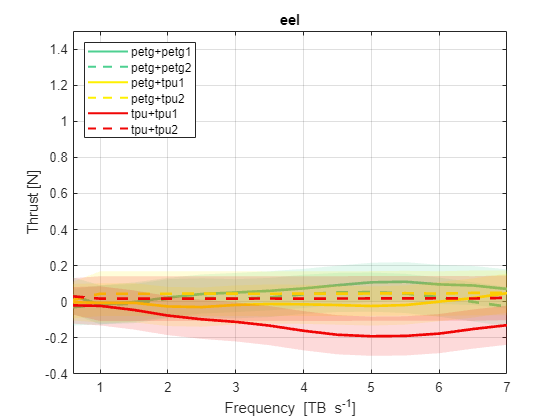

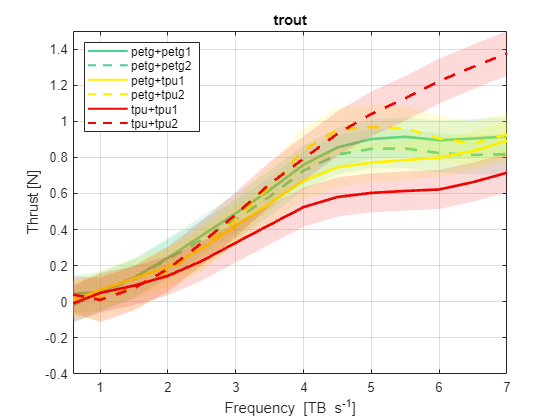

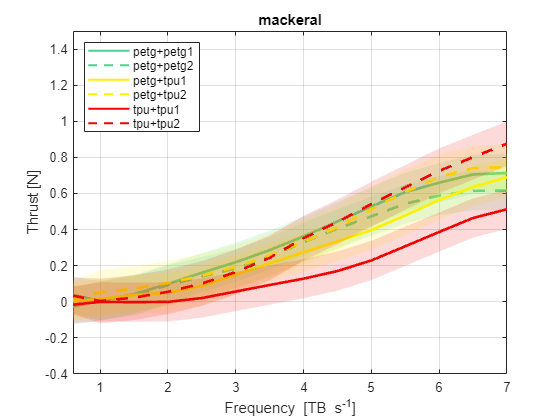

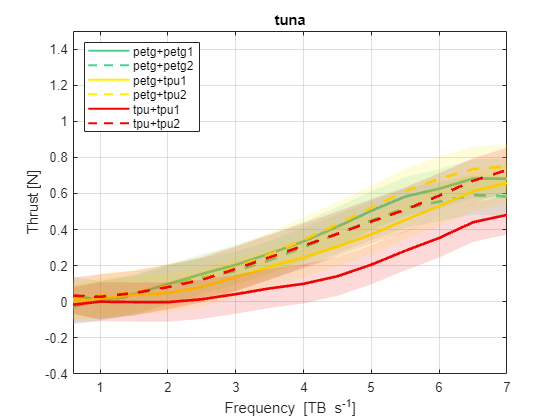

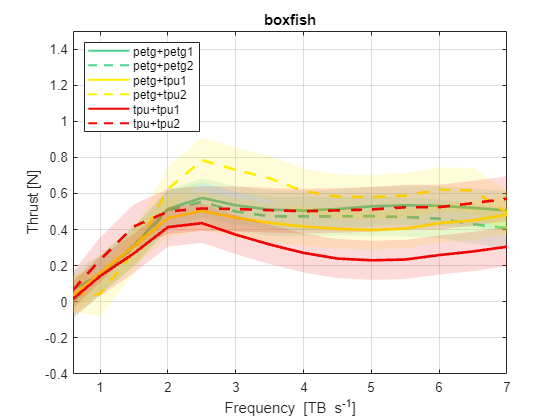

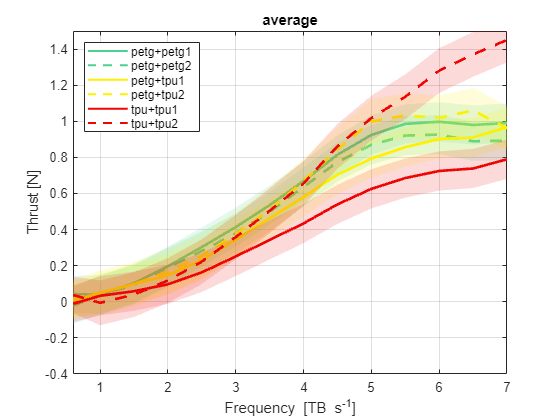

=== Best config per fin (model-predicted marginal mean) ===


    FinType    Material    Thickness    Frequency    Amplitude    ThrustHat    CI_low     CI_high
    _______    ________    _________    _________    _________    _________    _______    _______

      "1"        "1"          "1"          5.5          NaN        0.11112     0.04922    0.17302
      "2"        "3"          "2"            7          NaN         1.3757       1.305     1.4465
      "3"        "3"          "2"            7          NaN        0.87615      0.8054     0.9469
      "4"        "2"          "2"            7          NaN        0.74972     0.67898    0.82047
      "5"        "2"          "2"          2.5          NaN        0.78429     0.71354    0.85504
      "6"        "3"          "2"        

=== Best fin overall (among fin optima) ===


    FinType    Material    Thickness    Frequency    Amplitude    ThrustHat    CI_low    CI_high
    _______    ________    _________    _________    _________    _________    ______    _______

      "6"        "3"          "2"           7           NaN        1.4504      1.3797    1.5212 



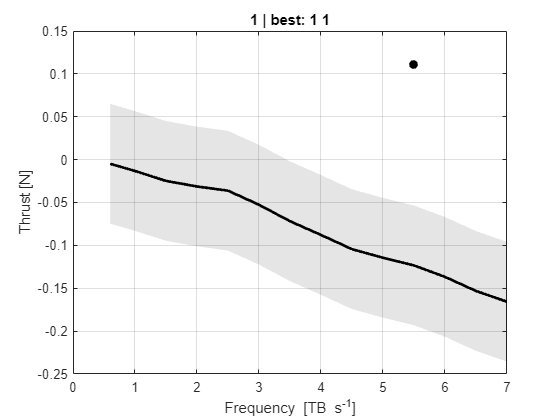

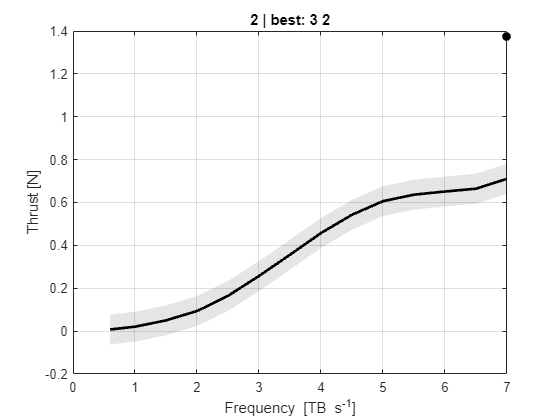

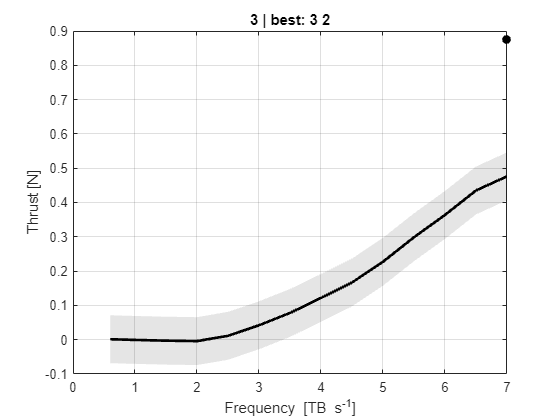

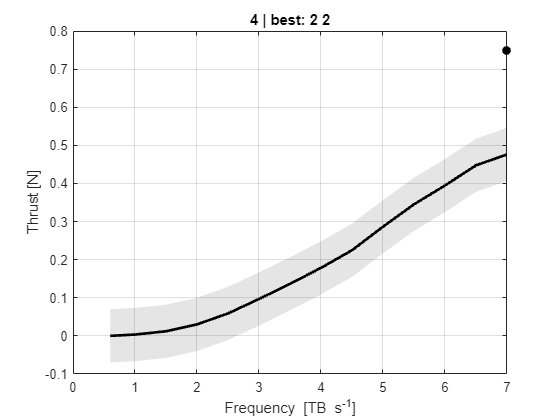

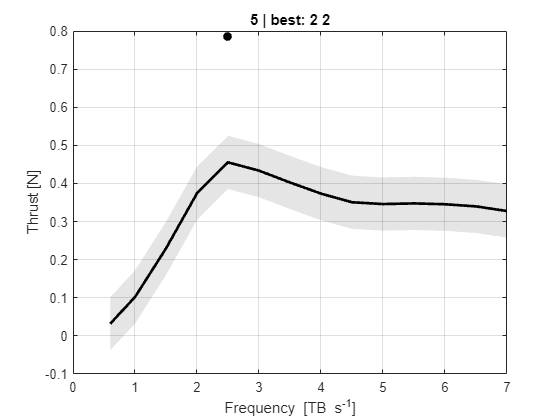

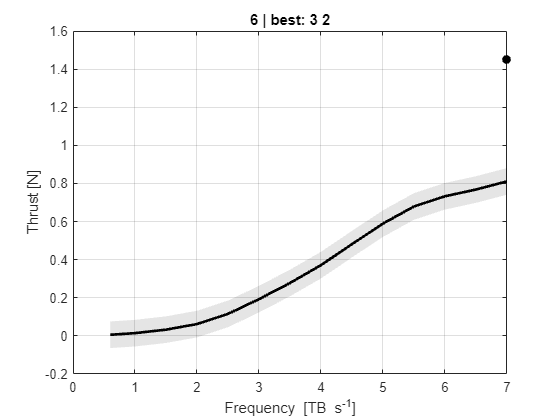

BestPerFin = 504×6 table
    FinType    Material    Thickness    Frequency    GroupCount    mean_Thrust
    _______    ________    _________    _________    __________    ___________

       1          1            1           0.6           6         -4.1598e-05
       1          1            1           1             6         -6.5337e-05
       1          1            1           1.5           6          2.8435e-05
       1          1            1           2             6         -4.7933e-05
       1          1            1           2.5           6          0.00032526
       1          1            1           3             6          0.00059785
       1          1            1           3.5           6          8.9358e-05
       1          1            1           4             6 

BestPerFin = 504×6 table
    FinType    Material    Thickness    Frequency    GroupCount    mean_Thrust
    _______    ________    _________    _________    __________    ___________

       6          3            2           7             6           1.4903   
       6          3            2           6.5           6           1.4103   
       2          3            2           7             6           1.4066   
       2          3            2           6.5           6           1.3324   
       6          3            2           6             6           1.3204   
       2          3            2           6             6           1.2533   
       6          3            2           5.5           6           1.1756   
       2          3            2           5.5           6 

Unrecognized function or variable 'duplicated'.

================ REPEATED MEASURES ANOVA =================


                                                       SumSq      DF     MeanSq       F     pValue    pValueGG    pValueHF    pValueLB
                                                      ________    __    _________    ___    ______    ________    ________    ________

    (Intercept)                                         3.4585     1       3.4585    NaN     NaN        NaN         NaN         NaN   
    FinType                                             1.0534     5      0.21068    NaN     NaN        NaN         NaN         NaN   
    Material                                          0.034262     2     0.017131    NaN     NaN        NaN         NaN         NaN   
 

================ MAUCHLY TEST =================


    W    ChiStat    DF     pValue
    _    _______    ___    ______

    1      NaN      860     NaN  



================ EPSILON CORRECTIONS =================


    Uncorrected    GreenhouseGeisser    HuynhFeldt    LowerBound
    ___________    _________________    __________    __________

         1                 1                1             1     



================ SUBJECT COUNTS =================


    FinType    Material    Thickness    GroupCount
    _______    ________    _________    __________

       1          1            1            1     
       1          1            2            1     
       1          2            1            1     
       1          2            2            1     
       1          3            1            1     
       1          3            2            1     
       2          1            1            1     
       2          1            2            1     
       2          2            1            1     
       2          2            2            1     
       2          3            1            1     
       2          3            2            1     
       3          1            1            1     
       3          1            2            1     
       3          2            1            1  

Analysis complete.


Results saved to workspace as:


  RM_Thrust_Results


  RM_Thrust_WideTable


  RM_Thrust_WithinDesign


  RM_Thrust_AveragedTable


Linear mixed-effects model fit by ML

Model information:
    Number of observations            9072
    Fixed effects coefficients        1512
    Random effects coefficients         36
    Covariance parameters                2

Formula:
    Thrust ~ 1 + FinType*Material + FinType*Thickness + Material*Thickness + FinType*Frequency + Material*Frequency + Thickness*Frequency + FinType*Amplitude + Material*Amplitude + Thickness*Amplitude + Frequency*Amplitude + FinType:Material:Thickness + FinType:Material:Frequency + FinType:Thickness:Frequency + Material:Thickness:Frequency + FinType:Material:Amplitude + FinType:Thickness:Amplitude + Material:Thickness:Amplitude + FinType:Frequency:Amplitude + Material:Frequency:Amplitude + Thickness:Frequency:Amplitude + FinType:Material:Thickness:Frequency + FinType:Material:Thickness:Amplitude + FinType:Material:Frequency:Amplitude + FinType:Thickness:Frequency:Amplitude + Material:Thickness:Frequen

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                                      FStat         DF1    DF2     pValue    
    {'(Intercept)'                                   }          0.001248      1    7560       0.97182
    {'FinType'                                       }              6.77      5    7560    2.6323e-06
    {'Material'                                      }          0.017647      2    7560       0.98251
    {'Thickness'                                     }        0.00021073      1    7560       0.98842
    {'Frequency'                                     }           0.26211     13    7560       0.99601
    {'Amplitude'                                     }         0.0012355      2    7560       0.99877
    {'FinType:Material'                              }            1.5297     10    7560       0.12184
    {'FinType:Thickness'                             }          0.027935      5    7560       0.99963
    {'Mate


for a = 1:nFin
    for b = a+1:nFin

        rowA = BestTable(a,:);
        rowB = BestTable(b,:);

        % replicates at each fin's own optimum condition
        idxA = string(DataTab.FinType)   == rowA.FinType & ...
               string(DataTab.Material)  == rowA.BestMaterial & ...
               string(DataTab.Thickness) == rowA.BestThickness & ...
               DataTab.Amplitude         == rowA.BestAmplitude & ...
               DataTab.Frequency         == rowA.OptimalFrequency;

        idxB = string(DataTab.FinType)   == rowB.FinType & ...
               string(DataTab.Material)  == rowB.BestMaterial & ...
               string(DataTab.Thickness) == rowB.BestThickness & ...
               DataTab.Amplitude         == rowB.BestAmplitude & ...
               DataTab.Frequency         == rowB.OptimalFrequency;

        yA = DataTab.(yvar)(idxA);
        yB = DataTab.(yvar)(idxB);

        [~,p] = ttest2(yA, yB, 'Alpha', alphaAdjFin);

        fprintf('%s vs %s: p = %.4g\n', rowA.FinType, rowB.FinType, p);
    end
end

function [DataTab, ymin, ymax] = beatanalysis(files, ax, color, meta)

    beatsum = [];

    a = 2.4064;
    b = -0.2175;
    lever_ratio = 24.8/36.5;

    DataTab = table();
    for i=1:length(files)
        if length(files(i).name) == 5
            file = [files(i).folder '\' files(i).name];
        else
            continue;
        end
        load(file);
        x = (data - b)/a;
        x = x*lever_ratio;

        x = extractFlaps(x,t,meta.Frequency);
        
        beatsum(:,end+1) = x;
        period = oscillating_period(x);
        datacell = {meta.FinID, meta.FinType, meta.Material, meta.Thickness, meta.Frequency, meta.Amplitude, i, mean(x),max(x),min(x),period(1),period(2)};
        Tab = cell2table(vertcat(datacell),"VariableNames", ...
            {'FinID','FinType','Material','Thickness','Frequency','Amplitude','ExperimentID','Thrust','MaxThrust','MaxDrag','PosPeriod','NegPeriod'});
        DataTab = [DataTab; Tab];
    end
    beatmean = mean(beatsum,2);
    beatstd = std(beatsum,1,2);
    mean_thrust = mean(mean(beatsum));

    ymin = min(beatmean - beatstd);
    ymax = max(beatmean + beatstd);

    hold(ax, 'on')
    plot(ax,t(1:length(x)),beatmean,'Color',color,'LineWidth',0.8)
    patch(ax,[t(1:length(x)); flip(t(1:length(x)))], [beatmean-beatstd; flip(beatmean+beatstd)],color,'FaceAlpha',0.25, 'EdgeColor','none')
    yline(ax,mean_thrust,'Color',color,'LineWidth',0.5)
    hold(ax, 'off')
end